# Emmanuelle Chaigneau

# Serge Charpak Laboratory

# Figure 6 Dual color ratiometric measurements

## Figure Parameters

Fig6TitleFontsize = 14 ;
Fig6LegendFontsize = 10 ;
Fig6AxisLabelFontsize = 12 ;
Fig6Linewidth = 2 ;

Figure6 = figure;
Figure6.Position = [10 10 900 600] ;
Figure6Layout = tiledlayout(2,6);
Figure6Layout.Padding = 'tight';

## Set up fittype and options

### For exponential time fitting.

ft = fittype( 'a0 * exp(x/T) ', 'independent', 'x', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.StartPoint = [10 1 ];
opts.Lower= [-100 0 ];


### For exponential depth fitting

ftz = fittype( 'exp(u*x)', 'independent', 'x', 'dependent', 'y' );
optsz = fitoptions( 'Method', 'NonlinearLeastSquares' );
optsz.StartPoint = 0.001;
optsz.Lower= 0;


## Load data files

load FRatioVsTimeAndDepth_2024Avr11.mat

Depth = FRatioVsTimeAndDepth(:,1);

Time1 = FRatioVsTimeAndDepth(:,2);
Time2 = FRatioVsTimeAndDepth(3:9,3);
Time3 = [FRatioVsTimeAndDepth(3:6,4); FRatioVsTimeAndDepth(8:9,4)];
Time4 = FRatioVsTimeAndDepth(3,5);

FR1 = FRatioVsTimeAndDepth(3:9,6) ;
FR2 = FRatioVsTimeAndDepth(3:9,7) ;
FR3 = [FRatioVsTimeAndDepth(3:6,8); FRatioVsTimeAndDepth(8:9,8)] ;
FR4 = FRatioVsTimeAndDepth(3,9) ;

TimeCap3 = FRatioVsTimeAndDepth(3,2:5);
FRCap3 = FRatioVsTimeAndDepth(3,6:9) ;

TimeConcat = [Time1(3:9) ; Time2 ; Time3 ; Time4];
DepthConcat = [Depth(3:9); Depth(3:9); Depth(3:6); Depth(8:9); Depth(3)];
FRConcat = [FR1 ; FR2 ; FR3 ; FR4];


## TDCCF data correction and averaging

### Surface data time fitting with exponential

[xData, yData] = prepareCurveData(TimeCap3, FRCap3 / FRCap3(1));
[fitresultCap3, ~] = fit( xData, yData, ft, opts)

fitresultCap3 =      General model:
     fitresultCap3(x) = a0 * exp(x/T)
     Coefficients (with 95% confidence bounds):
       T =       216.3  (78.14, 354.4)
       a0 =       0.957  (0.6584, 1.256)

fitcoeffvalsCap3= coeffvalues(fitresultCap3);

Tau = fitcoeffvalsCap3(1);
a0 = fitcoeffvalsCap3(2);


### TDCCF data correction

TDCCFFRConcat = FRConcat ./ (a0 * exp(TimeConcat./Tau) ) ;


### Fit TDCCF corrected FRatio versus depth 

DepthAvg = [15 47 95 150 200 250 300];

IdxZ15 = DepthConcat == 15 ;
IdxZ47 = DepthConcat == 47 ;
IdxZ95 = DepthConcat == 95 ;
IdxZ150 = DepthConcat == 150 ;
IdxZ200 = DepthConcat == 200 ;
IdxZ250 = DepthConcat == 250 ;
IdxZ300 = DepthConcat == 300 ;

TDCCFCorrectedAvg(1) = mean(TDCCFFRConcat(IdxZ15));
TDCCFCorrectedAvg(2) = mean(TDCCFFRConcat(IdxZ47));
TDCCFCorrectedAvg(3) = mean(TDCCFFRConcat(IdxZ95));
TDCCFCorrectedAvg(4) = mean(TDCCFFRConcat(IdxZ150));
TDCCFCorrectedAvg(5) = mean(TDCCFFRConcat(IdxZ200));
TDCCFCorrectedAvg(6) = mean(TDCCFFRConcat(IdxZ250));
TDCCFCorrectedAvg(7) = mean(TDCCFFRConcat(IdxZ300));

TDCCFCorrectedStd(1) = std(TDCCFFRConcat(IdxZ15));
TDCCFCorrectedStd(2) = std(TDCCFFRConcat(IdxZ47));
TDCCFCorrectedStd(3) = std(TDCCFFRConcat(IdxZ95));
TDCCFCorrectedStd(4) = std(TDCCFFRConcat(IdxZ150));
TDCCFCorrectedStd(5) = std(TDCCFFRConcat(IdxZ200));
TDCCFCorrectedStd(6) = std(TDCCFFRConcat(IdxZ250));
TDCCFCorrectedStd(7) = std(TDCCFFRConcat(IdxZ300));

FRatioNormCC = TDCCFCorrectedAvg / TDCCFCorrectedAvg(1) ;
FRatioNormCCStd = TDCCFCorrectedStd / TDCCFCorrectedAvg(1);


### Load spectral information

load('Lambda_Phi_HRuby.mat');
LambdaPhiNAS = Lambda_Phi_HRuby(:,1);
PhiNAS = Lambda_Phi_HRuby(:,2) / sum (Lambda_Phi_HRuby(:,2));

load('Lambda_Phi_AF488.mat');
LambdaPhiNB = Lambda_Phi_AF488(:,1);
PhiNB = Lambda_Phi_AF488(:,2) / sum (Lambda_Phi_AF488(:,2));

load('Lambda_MuABrainTot25.mat');
LambdaMuA = Lambda_MuABrainTot(:,1);
MuABrainTot = Lambda_MuABrainTot(:,2);

load('Lambda_MupsBrain.mat') ;
MupsBrain = Lambda_MupsBrain(:,2) ;

Lambda1 = 500 ;
Lambda2 = 550 ;
Lambda3 = 578 ;
Lambda4 = 640 ;

SigmaN = 26 / 10 ;  


### Set concentrations 

CS = 3.11 * 10^-6 ;
CB = 10^-5 ;
pKa = 7.47 ;                            
KARuby = 10^(-pKa) ;                    
pH0 = 7.4 ; 

CMS = CS / ( 1 + KARuby / 10^(-pH0) )   

CMS = 1.6800e-06

### Get values of interest

BooIdxMuALambda1to2 = logical( (LambdaMuA >= Lambda1) .* (LambdaMuA <= Lambda2) ) ;
BooIdxMuALambda3to4 = logical( (LambdaMuA >= Lambda3) .* (LambdaMuA <= Lambda4) ) ;

BooIdxASLambda3to4 = logical( (LambdaPhiNAS >= Lambda3) .* (LambdaPhiNAS <= Lambda4) ) ;

BooIdxBLambda1to2 = logical( (LambdaPhiNB >= Lambda1) .* (LambdaPhiNB <= Lambda2) ) ;
BooIdxBLambda3to4 = logical( (LambdaPhiNB >= Lambda3) .* (LambdaPhiNB <= Lambda4) ) ;


## Panel A

## Data from individual experiment fitting

PanelA1 = nexttile([1 3]) ;

zCC = 0 : 1 : 500 ;


### AbSc model

### Find AeOpt XBloodOpt and calculate fit with optimized AbSc model 

[AeOptCC, SumResidualsCC, R2CC, XBloodOpt] = FindAeAndXBloodOptAbScModelPhi(0.69, MuABrainTot, MupsBrain,  DepthAvg, PhiNAS, PhiNB, BooIdxMuALambda3to4, ...
    BooIdxASLambda3to4, BooIdxBLambda3to4, BooIdxMuALambda1to2, BooIdxBLambda1to2, CMS, CB, SigmaN, FRatioNormCC')

Difftest =     0.1393    0.1086    0.0848    0.0657    0.0502    0.0377    0.0280    0.0206    0.0156    0.0127    0.0119    0.0132    0.0166    0.0220    0.0295
    0.1454    0.1151    0.0913    0.0719    0.0559    0.0427    0.0321    0.0237    0.0174    0.0132    0.0110    0.0107    0.0123    0.0159    0.0214
    0.1508    0.1209    0.0971    0.0776    0.0612    0.0475    0.0361    0.0269    0.0197    0.0144    0.0109    0.0093    0.0096    0.0117    0.0157
    0.1554    0.1260    0.1024    0.0827    0.0660    0.0519    0.0400    0.0301    0.0221    0.0159    0.0115    0.0088    0.0080    0.0089    0.0116
    0.1594    0.1304    0.1070    0.0873    0.0704    0.0559    0.0436    0.0331    0.0244    0.0175    0.0123    0.0089    0.0071    0.0070    0.0088
    0.1627    0.1342    0.1109    0.0912    0.0742    0.0595    0.0468    0.0359    0.0267    0.0192    0.0133    0.0092    0.0067    0.0059    0.0069
    0.1654    0.1374    0.1143    0.0946    0.0775    0.0626    0.0496    0.0383   

LinIdxOptRow =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10
    11
    12
    13
    14
    15


LinIdxOptCol =     11
    12
    12
    13
    14
    14
    14
    15
    15
    15
    15
    15
    15
    15
    15


IdxXBloodOpt = 15

AeOptCC = 2.1000

SumResidualsCC = 0.0036

R2CC = 0.9722

XBloodOpt = 8


[PhiAS34Opt, PhiB34Opt, PhiB12Opt] = TricoliCoefs1234Phi(AeOptCC, 0.69, XBloodOpt*MuABrainTot/2.5, MupsBrain, ...
    zCC, PhiNAS, PhiNB, BooIdxMuALambda3to4, BooIdxASLambda3to4, BooIdxBLambda3to4, BooIdxMuALambda1to2, BooIdxBLambda1to2) ;

FRatioAbScModelCC = CMS * SigmaN / CB * PhiAS34Opt ./ PhiB12Opt + PhiB34Opt ./ PhiB12Opt ;


### AbSc model using average values cortex from experiments with Texas Red + Fluorescein

[PhiAS34Avg, PhiB34Avg, PhiB12Avg] = TricoliCoefs1234Phi(1.5, 0.69, 5.2*MuABrainTot/2.5, MupsBrain, ...
    zCC, PhiNAS, PhiNB, BooIdxMuALambda3to4, BooIdxASLambda3to4, BooIdxBLambda3to4, BooIdxMuALambda1to2, BooIdxBLambda1to2) ;

FRatioAbScModelCC_Avg = CMS * SigmaN / CB * PhiAS34Avg ./ PhiB12Avg + PhiB34Avg ./ PhiB12Avg ;

[PhiAS34Avg, PhiB34Avg, PhiB12Avg] = TricoliCoefs1234Phi(1.5, 0.69, 5.2*MuABrainTot/2.5, MupsBrain, ...
    DepthAvg, PhiNAS, PhiNB, BooIdxMuALambda3to4, BooIdxASLambda3to4, BooIdxBLambda3to4, BooIdxMuALambda1to2, BooIdxBLambda1to2) ;

FRatioAbScModelCC_Avg_pH = CMS * SigmaN / CB * PhiAS34Avg ./ PhiB12Avg + PhiB34Avg ./ PhiB12Avg ;

SumResidualsAbScAvgModelCC = sum((FRatioNormCC' - (FRatioAbScModelCC_Avg_pH / FRatioAbScModelCC_Avg_pH(1))').^2)

SumResidualsAbScAvgModelCC = 0.0235


R2AbScAvgModelCC = 1 - (sum((FRatioNormCC' - (FRatioAbScModelCC_Avg_pH / FRatioAbScModelCC_Avg_pH(1))').^2) / ...
    sum((FRatioNormCC' - mean(FRatioNormCC,2)).^2))

R2AbScAvgModelCC = 0.8194

### Exponential fit 

[xDataAvg, yDataAvg] = prepareCurveData(DepthAvg, FRatioNormCC);
[fitresultzAvg, gof] = fit( xDataAvg, yDataAvg, ftz, optsz)

fitresultzAvg =      General model:
     fitresultzAvg(x) = exp(u*x)
     Coefficients (with 95% confidence bounds):
       u =   0.0008871  (0.0006469, 0.001127)

gof = struct with fields:
           sse: 0.0203
       rsquare: 0.8441
           dfe: 6
    adjrsquare: 0.8441
          rmse: 0.0581


fitcoeffvalszAvg = coeffvalues(fitresultzAvg);
ConfMatFitzAvg = confint(fitresultzAvg,0.95);
uDataAvg = fitcoeffvalszAvg(1) ;

FRatio_ExpFit_pH = exp(uDataAvg * DepthAvg) ;

SumResidualsExpFit = sum((FRatioNormCC' - (FRatio_ExpFit_pH)').^2)

SumResidualsExpFit = 0.0203


R2ExpFit = 1 - (sum((FRatioNormCC' - (FRatio_ExpFit_pH)').^2) / sum((FRatioNormCC' - mean(FRatioNormCC,2)).^2))

R2ExpFit = 0.8441

### Plot Results

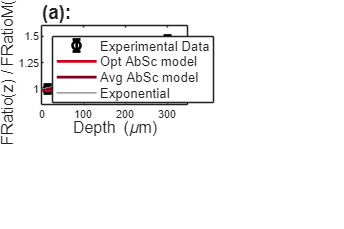

hDatazAvg = errorbar(DepthAvg, FRatioNormCC, FRatioNormCCStd, 'ko');
hold on
hAbScModelCC = plot (zCC, FRatioAbScModelCC / FRatioAbScModelCC(1), '-') ;
hAbScModelCC_AeAvg_XbloodAvg = plot (zCC, FRatioAbScModelCC_Avg / FRatioAbScModelCC_Avg(1), '-') ;
hfitz = plot(fitresultzAvg) ;
hold off

hDatazAvg.LineWidth = 2 ;
hAbScModelCC.LineWidth = 2 ;
hAbScModelCC.Color = [0.8 0 0.1] ;
hAbScModelCC_AeAvg_XbloodAvg.LineWidth = 2 ;
hAbScModelCC_AeAvg_XbloodAvg.Color = [0.5 0 0.1] ;
hfitz.LineWidth = 1 ;
hfitz.Color = [0.5 0.5 0.5] ;

legend('Experimental Data', 'Opt AbSc model', 'Avg AbSc model', 'Exponential','Location', 'NorthWest', ...
    "FontSize", Fig6LegendFontsize);
xlabel("Depth (\mum)", "FontSize", Fig6AxisLabelFontsize)
ylabel("FRatio(z) / FRatioM(0)", "FontSize", Fig6AxisLabelFontsize )
axis([0 350 0.85 1.6]);
xticks([0 100 200 300]);
yticks([1 1.25 1.5]);

title('(a):', 'FontSize', Fig6TitleFontsize)
ax = gca;
ax.TitleHorizontalAlignment = 'left';

## Panel B

## Calculation of pH from individual experiment 

nexttile([1 3])


### Calculation of constants

PhiN0AS34 = sum(PhiNAS(BooIdxASLambda3to4)) 

PhiN0AS34 = 0.6104

PhiN0B12 = sum(PhiNB(BooIdxBLambda1to2)) 

PhiN0B12 = 0.7337

PhiN0B34 = sum(PhiNB(BooIdxBLambda3to4)) 

PhiN0B34 = 0.0771


N34DivN12z0 = CMS * SigmaN * PhiN0AS34 / ( CB * PhiN0B12 ) + PhiN0B34 / PhiN0B12

N34DivN12z0 = 0.4686

### Calculation of pH without any depth-correction

pHz_raw = pKa + log10(CS * SigmaN * PhiN0AS34 ./ ...
    (CB * (N34DivN12z0 * FRatioNormCC .* PhiN0B12 - PhiN0B34 ) ) - 1) ;


### pH with AbSc correction and optimized Xblood and optimized ae correction

[PhiAS34Opt_pH, PhiB34Opt_pH, PhiB12Opt_pH] = TricoliCoefs1234Phi(AeOptCC, 0.69, XBloodOpt*MuABrainTot/2.5, MupsBrain, ...
    DepthAvg, PhiNAS, PhiNB, BooIdxMuALambda3to4, BooIdxASLambda3to4, BooIdxBLambda3to4, BooIdxMuALambda1to2, BooIdxBLambda1to2) ;

FRatioAbScModelCC_pH = CMS * SigmaN / CB * PhiAS34Opt_pH ./ PhiB12Opt_pH + PhiB34Opt_pH ./ PhiB12Opt_pH ;

pHz_aeOpt_XbloodOpt = pKa + log10(CS * SigmaN * PhiAS34Opt_pH ./ ...
    (CB * (FRatioNormCC * FRatioAbScModelCC_pH(1) .* PhiB12Opt_pH - PhiB34Opt_pH)) - 1) ;


### pH with AbSc correction and average Xblood and average ae correction

pHz_aeAvg_XbloodAvg = pKa + log10(CS * SigmaN * PhiAS34Avg ./ ...
    (CB * (FRatioNormCC * FRatioAbScModelCC_Avg(1) .* PhiB12Avg - PhiB34Avg ) ) - 1) ;



### pH with Exponential fit correction

pHz_Exp = pKa + log10(CS * SigmaN * PhiN0AS34 ./ ...
    (CB * (N34DivN12z0 * FRatioNormCC .* exp(-uDataAvg * DepthAvg) .* PhiN0B12 - PhiN0B34)) - 1) ;


### Plot results

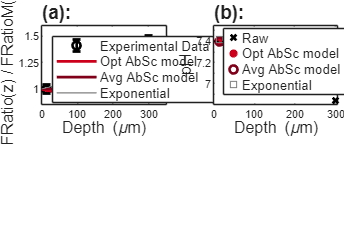

hpHRaw = plot(DepthAvg, pHz_raw,'kx') ;
hold on
hpH_AbScCor_Opt = plot (DepthAvg, pHz_aeOpt_XbloodOpt, '*') ;
hpH_AbScCor_Avg = plot (DepthAvg, pHz_aeAvg_XbloodAvg, 'o') ;
hpH_ExpfitCor = plot(DepthAvg, pHz_Exp, "square") ;
hpH74 = plot(0:1:305, 7.4 * ones (306, 1), 'k:') ;
hold off

hpHRaw.LineWidth = 2 ;
hpH_AbScCor_Opt.LineWidth = 2 ;
hpH_AbScCor_Opt.Color = [0.8 0 0.1] ;
hpH_AbScCor_Avg.LineWidth = 2 ;
hpH_AbScCor_Avg.Color = [0.5 0 0.1] ;
hpH_ExpfitCor.LineWidth = 1 ;
hpH_ExpfitCor.Color = [0.5 0.5 0.5] ;

legend('Raw', 'Opt AbSc model', 'Avg AbSc model', 'Exponential','Location', 'SouthWest', ...
      "FontSize", Fig6LegendFontsize);
xlabel("Depth (\mum)", "FontSize", Fig6AxisLabelFontsize)
ylabel("pH", "FontSize", Fig6AxisLabelFontsize )
axis([0 305 6.8 7.55]);
xticks([0 100 200 300 400 500]);
yticks([6.9 7 7.1 7.2 7.3 7.4 7.5]);
yticklabels({'', '7', '', '7.2', '', '7.4', ''});

title('(b):', 'FontSize', Fig6TitleFontsize)
ax = gca;
ax.TitleHorizontalAlignment = 'left';

## Panel C

## Residual error using depth correction with AbSc model and optimized parameters

### Load and merge data containing residual errors after depth correction

load('DeltapH_2025Jun09.mat')
load('DeltapH_2024avr11.mat')

DeltapH = [ DeltapH_2025Jun09 , DeltapH_2024avr11 ]

DeltapH =          0   -0.0301    0.0138    0.0003   -0.0271   -0.0335    0.0402   -0.0182    0.0214    0.0251   -0.0219         0    0.0376   -0.0488    0.0033    0.0203    0.0200   -0.0132
         0   -0.0310    0.0169    0.0102   -0.0073   -0.0058    0.0756    0.0306    0.0775    0.0919    0.0580         0    0.0546   -0.0337   -0.0059   -0.0191   -0.0551   -0.1326
    0.0022   -0.0033    0.0527    0.0437    0.0148    0.0029    0.0634   -0.0072    0.0179    0.0040   -0.0617    0.0161    0.0935    0.0300    0.0644    0.0504    0.0088   -0.0770



MeanDeltapH = mean(DeltapH,1)

MeanDeltapH =     0.0007   -0.0214    0.0278    0.0181   -0.0066   -0.0121    0.0597    0.0017    0.0389    0.0403   -0.0085    0.0054    0.0619   -0.0175    0.0206    0.0172   -0.0088   -0.0743


SdtDeltapH = std(DeltapH,1)

SdtDeltapH =     0.0010    0.0129    0.0177    0.0186    0.0171    0.0155    0.0147    0.0209    0.0273    0.0375    0.0498    0.0076    0.0234    0.0341    0.0312    0.0285    0.0331    0.0488



HisEdges = -0.17: 0.02 : 0.17 ;

x_HistFit = -0.2 : 0.001 : 0.2 ;


### Calculate and plot distribution of remaining error using depth correction with AbSc model and optimized parameters

nexttile([1 2])

pd_pHz_AbScModel_Opt = fitdist(DeltapH (1,:)','Normal') 

pd_pHz_AbScModel_Opt =   NormalDistribution

  Normal distribution
       mu = -0.000599098   [-0.0133879, 0.0121897]
    sigma =     0.025717   [0.0192977, 0.0385535]


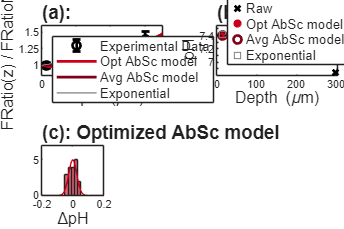

y_Histfit_pd_pHz_AbScModel_Opt = pdf(pd_pHz_AbScModel_Opt, x_HistFit) * 5 / ...
    max(pdf(pd_pHz_AbScModel_Opt, x_HistFit));

Hist_pHz_AbScModel_Opt = histogram(DeltapH (1,:), 'BinEdges', HisEdges) ;
hold on
Histfit_pd_pHz_AbScModel_Opt = plot(x_HistFit, y_Histfit_pd_pHz_AbScModel_Opt) ;
hold off

Hist_pHz_AbScModel_Opt.FaceColor = [0.8 0 0.1] ;
Histfit_pd_pHz_AbScModel_Opt.Color = [0.8 0 0.1] ;

axis([-0.2 0.2 0 7]);
xlabel("\DeltapH", "FontSize", Fig6AxisLabelFontsize )

title('(c): Optimized AbSc model', 'FontSize', Fig6TitleFontsize)
ax = gca;
ax.TitleHorizontalAlignment = 'left';

## Panel D

## Residual error using depth correction with AbSc model and average parameters

### Calculate and plot distribution of residual error using depth correction with AbSc model and average parameters

nexttile([1 2])

pd_pHz_AbScModel_Avg = fitdist(DeltapH (2,:)','Normal')

pd_pHz_AbScModel_Avg =   NormalDistribution

  Normal distribution
       mu = 0.0069378   [-0.020077, 0.0339527]
    sigma = 0.0543243   [0.0407643, 0.08144]


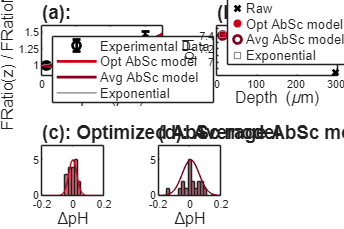

y_Histfit_pd_pHz_AbScModel_Avg = pdf(pd_pHz_AbScModel_Avg, x_HistFit) * 5 / ...
    max(pdf(pd_pHz_AbScModel_Avg, x_HistFit));

Hist_pHz_AbScModel_Avg = histogram(DeltapH (2,:), 'BinEdges', HisEdges) ;
hold on 
Histfit_pd_pHz_AbScModel_Avg = plot(x_HistFit, y_Histfit_pd_pHz_AbScModel_Avg) ;
hold off

Hist_pHz_AbScModel_Avg.FaceColor = [0.5 0 0.1] ;
Histfit_pd_pHz_AbScModel_Avg.Color = [0.5 0 0.1] ;

axis([-0.2 0.2 0 7]);
xlabel("\DeltapH", "FontSize", Fig6AxisLabelFontsize )

title('(d): Average AbSc model', 'FontSize', Fig6TitleFontsize)
ax = gca;
ax.TitleHorizontalAlignment = 'left';

## Panel E

## Residual error using exponential correction

### Calculate and plot distribution of residual error using exponential correction

nexttile([1 2])

pd_pHz_Exp = fitdist(DeltapH (3,:)','Normal')

pd_pHz_Exp =   NormalDistribution

  Normal distribution
       mu = 0.0175328   [-0.00342725, 0.0384929]
    sigma = 0.0421488   [0.0316279, 0.0631871]


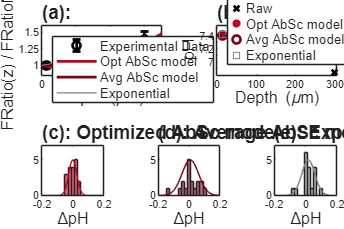


y_Histfit_pd_pHz_Exp = pdf(pd_pHz_Exp, x_HistFit) * 5 / ...
    max(pdf(pd_pHz_Exp, x_HistFit));

Hist_pHz_Exp = histogram(DeltapH (3,:), 'BinEdges', HisEdges) ;
hold on 
Histfit_pd_pHz_Exp = plot(x_HistFit, y_Histfit_pd_pHz_Exp) ;
hold off

Hist_pHz_Exp.FaceColor = [0.5 0.5 0.5]  ;
Histfit_pd_pHz_Exp.Color = [0.5 0.5 0.5]  ;

axis([-0.2 0.2 0 7]);
xlabel("\DeltapH", "FontSize", Fig6AxisLabelFontsize )

title('(e): Exponential', 'FontSize', Fig6TitleFontsize)
ax = gca;
ax.TitleHorizontalAlignment = 'left';